clc
clear 
close all

Reading the Cimel Data

cimelData = readtable('20170715.dat'); 

% using the function date2doy to get dateofYear
% char is used because the datenum can't work with the sting class type.
[cimel_doy,~,~] = date2doy(datenum(cimelData.Var1));

% Astronomical distance based on the chander table for the given doy 196 is 
%https://ac.els-cdn.com/S0034425709000169/1-s2.0-S0034425709000169-main.pdf?_tid=446cb217-94c9-40b6-a4f3-b90de3f319c4&acdnat=1538148381_c3189ee5f772c9c039f0ba29ab140fc5
astDistance = 1.01646;

% squaring the astronomical Distance
sqAstDistance = astDistance .^2;


for dataRead = 1:size(cimelData,1)
    dateVariable = cimelData.Var1(dataRead);
    time.year = cimelData.Var1(dataRead).Year;
    time.month = cimelData.Var1(dataRead).Month;
    time.day = cimelData.Var1(dataRead).Day;
    timeValue = strsplit(cimelData.Var2{dataRead},':');
    time.hour = str2double(timeValue{1});
    time.min =  str2double(timeValue{2});
    time.sec =  str2double(timeValue{3});
    time.UTC = 0;  ... confusion in this line
    
    
     % creating the location structure
     % the information is generated from the google maps
      location.latitude = 44.291;
      location.longitude = -96.765;
      location.altitude = 505;
       % calling the function sun_position
    [sunInfo] = sun_position(time,location);
    cimel_sunZenith(:,dataRead) = sunInfo.zenith;
    cimel_sunAzimuth(:,dataRead) = sunInfo.azimuth;
end
timeValuer = datetime(cimelData.Var2,'InputFormat','HH:mm:ss');
timevalue = timeValuer.Hour-5 + timeValuer.Minute/60 + timeValuer.Second/360;

## Plotting the Solar Zenith angle and Solar azimuth angle

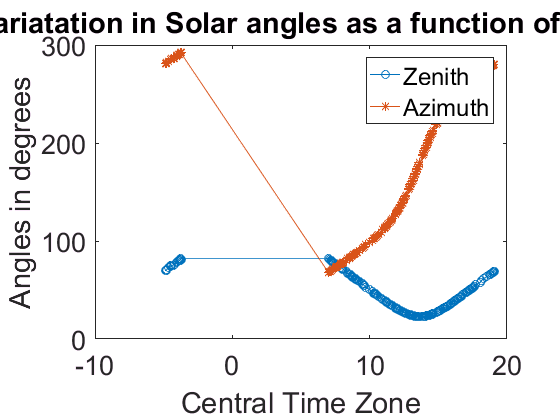

figure 
plot(timevalue,cimel_sunZenith,'Marker','o')
hold on
plot(timevalue,cimel_sunAzimuth,'Marker','*')
title('Variatation in Solar angles as a function of time');
xlabel('Central Time Zone');
ylabel('Angles in degrees')
legend('Zenith','Azimuth');
ax = gca;
ax.FontSize = 20;

**Calculating the arimass**

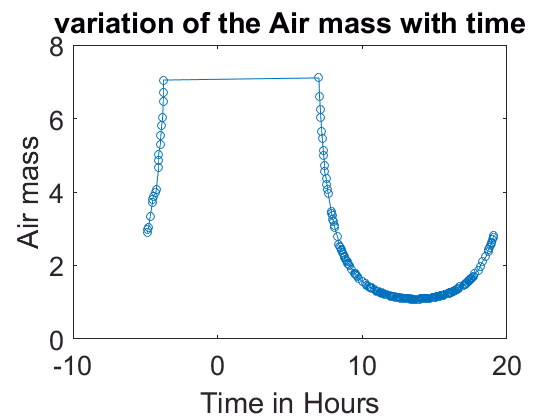

airmass = ones(size(cimelData,1),1) ./ cosd(cimel_sunZenith');

figure 
plot(timevalue, airmass,'Marker','o')
xlabel('Time in Hours')
ylabel('Air mass')
title('variation of the Air mass with time')
ax = gca;
ax.FontSize = 20;

## Section Datas witht he data preparation for the Plotting

wavelengthColRange= [3,5,7:12];
waterWavelength = 9;
wavelengthName = {'1640','1020','870','675','500','440','380','340'};
waterWavelengthName = {'937'};
wavelength = [1640,1020,870,675,500,440,380,340];
wavelength = (wavelength);



$$ln\left(V_{\lambda \text{ }} ∗D^2 \right)$$


% multipying the bands output with the astronomical distance and taking the log
for band = 3:12
    % curly brackes has to be used to extract data for multiplication
    bandSel = cimelData{:,band};
    ymultiple =  sqAstDistance * bandSel;
    %taking the natural logarith of the  ymultiple
    logTransformedV(:,band-2) = log(ymultiple);
end

% finding the inf values on the list
[infiniteRow,~] = find(logTransformedV == Inf | logTransformedV == -Inf);

% removing the infinite value from both airmass and logResponse
logTransformedV(infiniteRow,:) = [];
airmass(infiniteRow) = [];


## Plotting the airmass and log transformed V value


% 
% figure 
% for i = 1:length(airmass)
%     plot(airmass(i), logTransformedV(i,1),'Marker','o');
%     title('Log Transformed Cimel Data as function of Air mass');
%     xlabel('Air Mass (m)');
%     ylabel('log(V*D^2)');
%     text(airmass(i),logTransformedV(i),num2str(i));
%     ax = gca;
%     ax.FontSize = 20;
%     hold on
% end
% 

## Plotting the airmass and log Transformed v Value breaked

subset(1).a = 1:9;
subset(2).a = 10:14;
subset(3).a = 15:19;
subset(4).a = 20:38;
subset(5).a = 39:50;
subset(6).a = 61:70;
subset(7).a = 71:120;
subset(8).a = 121:199;


## Plotting the Optical Depth against log Response

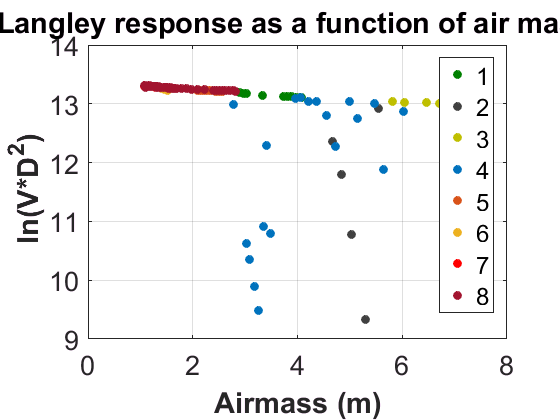

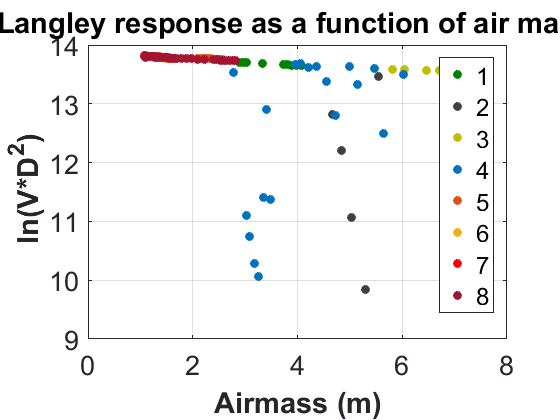

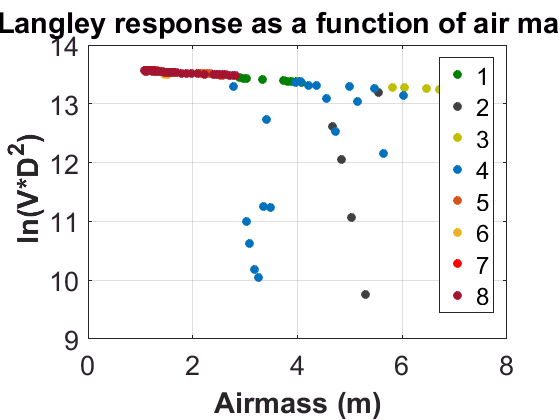

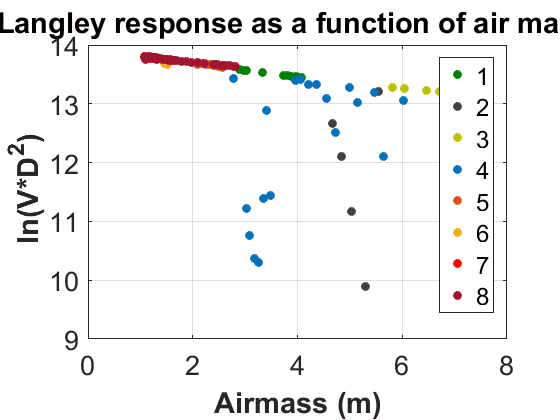

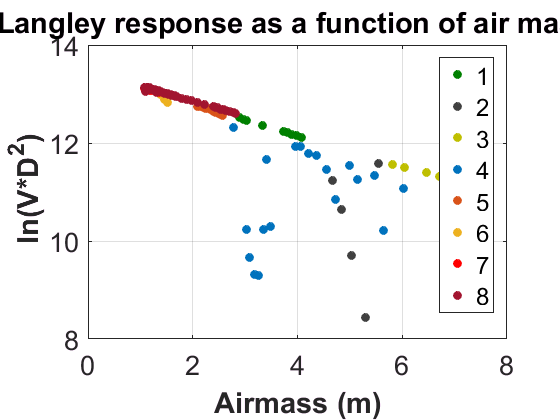

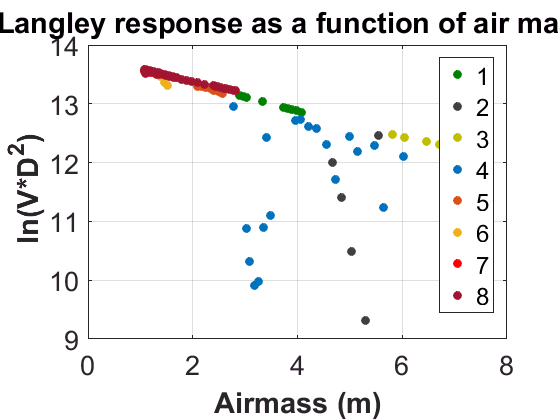

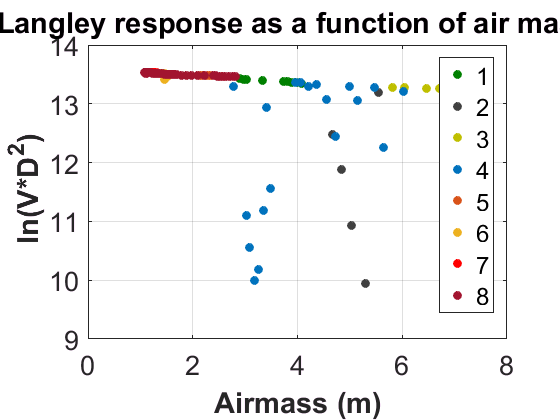

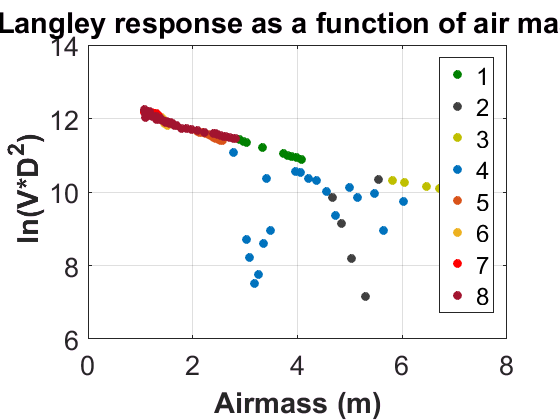



for band = 1: length(wavelengthName)
    figure
    % random  error till 8:6:5 am
    plot(airmass(1:9),logTransformedV(1:9,band),'Marker','o','LineStyle','None','Color',[0, 0.5, 0],'MarkerFaceColor',[0, 0.5, 0])
    hold on
    plot(airmass(10:14),logTransformedV(10:14,band),'Marker','o','LineStyle','None','Color',[0.25, 0.25, 0.25],'MarkerFaceColor',[0.25, 0.25, 0.25])
    hold on
    % till 1:40:5  PM til angle is decreasing
    plot(airmass(15:19),logTransformedV(15:19,band),'Marker','o','LineStyle','None','Color',[0.75, 0.75, 0],'MarkerFaceColor',[0.75, 0.75, 0])
    hold on 
    plot(airmass(20:38),logTransformedV(20:38,band),'Marker','o','LineStyle','None','Color',[0, 0.4470, 0.7410],'MarkerFaceColor',[0, 0.4470, 0.7410])
    hold on
    plot(airmass(39:50),logTransformedV(39:50,band),'Marker','o','LineStyle','None','Color',[0.8500, 0.3250, 0.0980],'MarkerFaceColor',[0.8500, 0.3250, 0.0980])
    hold on 
    plot(airmass(62:70),logTransformedV(62:70,band),'Marker','o','LineStyle','None','Color',[0.9290, 0.6940, 0.1250],'MarkerFaceColor',[0.9290, 0.6940, 0.1250])
    hold on 
    plot(airmass(71:120),logTransformedV(71:120,band),'Marker','o','LineStyle','None','Color',[1, 0, 0],'MarkerFaceColor',[1, 0, 0])
    hold on 
    plot(airmass(121:199),logTransformedV(121:199,band),'Marker','o','LineStyle','None','Color',[0.6350, 0.0780, 0.1840],'MarkerFaceColor',[0.6350, 0.0780, 0.1840])
    hold on
%     plot(opticalDepth(48:382),logResponse(48:382,band),'Marker','o','LineStyle','None')
%     hold on 
    % 1:40:5angle start increasing
%     plot(opticalDepth(383:end),logResponse(383:end,band),'Marker','o','LineStyle','None')
    xlabel('Airmass (m)','FontWeight','bold');
    ylabel(' ln(V*D^2)','FontWeight','bold');
    title('Langley response as a function of air mass ')
    legend('1','2','3','4','5','6','7','8')
    ax = gca;
    ax.FontSize = 20;
    hold on
    grid on
end

## Fitting  a line on the value

for i = 1:8
    logResponse1 = logTransformedV(subset(i).a,:);
    opticalDepth1 = airmass(subset(i).a);
%        logResponse1 = logResponse
%        opticalDepth1 = opticalDepth
    summaryCell = cell(7,6);
    % predictedReflectance = zeros(size(solarFiltered,1),7);
    % fitting regression line for the each band 
    for band =  1:length(wavelengthName) 
        % Entering all the data into the table for the linear fit
        lineFitTable = table(logResponse1(:,band),opticalDepth1);
        lineFitTable.Properties.VariableNames = {'yResponse','xPredictor'};
        model  = fitlm(lineFitTable,'yResponse ~ xPredictor','Robust','on');
        % coefficients of the linear fit 
        [coeffrow ,~] = size(model.Coefficients.Estimate);
%         figure 
%         plot(model,'Marker','o');
%         titleText = strcat('Linear Model fit of',{' '}, wavelengthName{band});
%         title(titleText)
%         xlabel('AirMass (m)');
%         ylabel('y');
%         legend(wavelengthName{band});
%         ax = gca;
%         ax.FontSize = 20;
        
%         leveragethreshold = 2*1/size(lineFitTable,1);
%         highLeveragePoints = find(leveragethreshold > model.Diagnostics.Leverage);
        
        % cooks distance  to check if any points are influencing the line more
        % than the otheres
        % Cookd Distance greater than 0.5 are points needed to be investigated
        % Cookd Distance greater that 1 are potential outliers in the data
%     %     figure
%     %     plotDiagnostics(model,'cookd')
%         cookDisOut = [find((model.Diagnostics.CooksDistance)> 5*mean(model.Diagnostics.CooksDistance));cookDisOut];
       
    %     figure
    %     bar(model.Diagnostics.CooksDistance)
       
        
%         % Displaying the model fit statistics 
%         disp(strcat('#######################################################'));
%         textValue = strcat('Model ' , num2str(band), wavelengthName{band}); 
%         warning(textValue);
%         disp(model)
%         
%         %{
%         H0: The relationship assumed in the model is reasonable, i.e., there is no lack of fit.
%         HA: The relationship assumed in the model is not reasonable, i.e., there is lack of fit.
%         %}
%         
%         % analysis of variance 
%         anova(model,'summary')
%         
%         disp(strcat('#######################################################'));
        
        summaryCell(band,:) = {wavelengthName{band}; model.Rsquared.Ordinary*100; ...
            model.Rsquared.Adjusted*100; model.RMSE*100; model.Coefficients.Estimate(1); ...
            model.Coefficients.Estimate(2)}; 
        
    end
    summaryTable(i).a = cell2table(summaryCell);
    clear summaryCell
    summaryTable(i).a.Properties.VariableNames = {'Band', 'Rsquared', ...
        'AdjustedRsquared', 'RMSE','Intercept','Slope'};
end


## calculating  the calibration constant

for i = 1:8
    calibration_Contant(:,i) = exp(summaryTable(i).a.Intercept);
end


**Calculating the Rayleigh scattering**

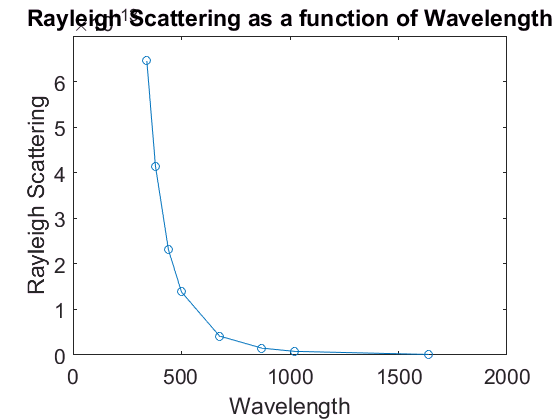

ray.a = 0.008569;
ray.b = 0.0113;
ray.c = 0.00013;
% https://www.timeanddate.com/weather/usa/brookings/historic?month=7&year=2017
pValue = 30.17;
%https://en.wikipedia.org/wiki/Atmospheric_pressure
pAbsolute = 29.921;


for wave = 1:length(wavelength)
    rayLeighValue(wave) = (ray.a*(wavelength(wave)^(-4)) * (1 + ray.b*(wavelength(wave)^(-2) + ray.c*(wavelength(wave)^(-4)))))*pValue/pAbsolute;
end

figure
plot(wavelength,rayLeighValue,'Marker','o')
xlabel('Wavelength')
ylabel('Rayleigh Scattering')
title('Rayleigh Scattering as a function of Wavelength')
ax = gca;
ax.FontSize = 16;

## calculating the aerosol value

for i = 1:8
    summaryTable(i).a.Tau_aerosol = abs(summaryTable(i).a.Slope) - transpose(rayLeighValue);
end



## plotting the each band to extract the information at 936nm

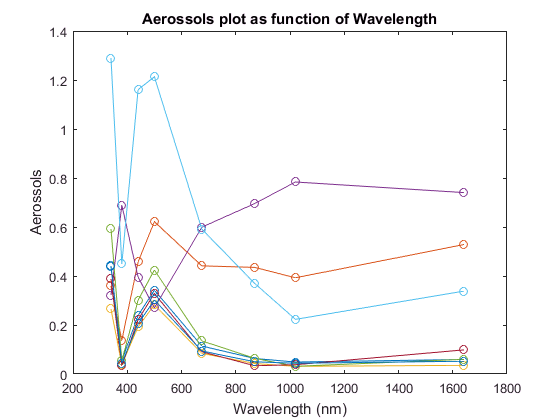

figure
for i =1:8
     plot(wavelength,summaryTable(i).a.Tau_aerosol,'Marker','o')
     xlabel('Wavelength (nm)');
     ylabel('Aerossols');
     title('Aerossols plot as function of Wavelength');
     hold on
 end

## Fitting for each equation

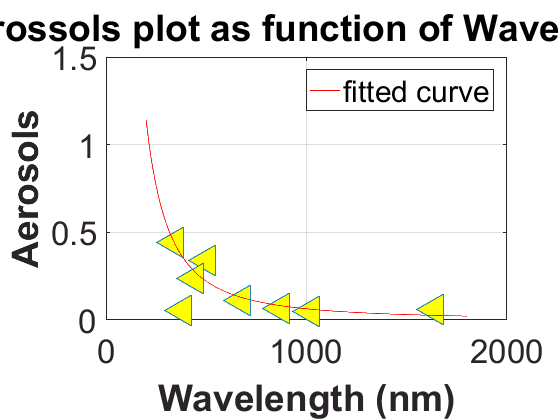

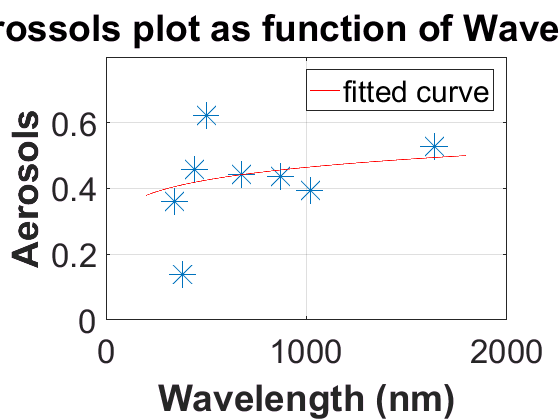

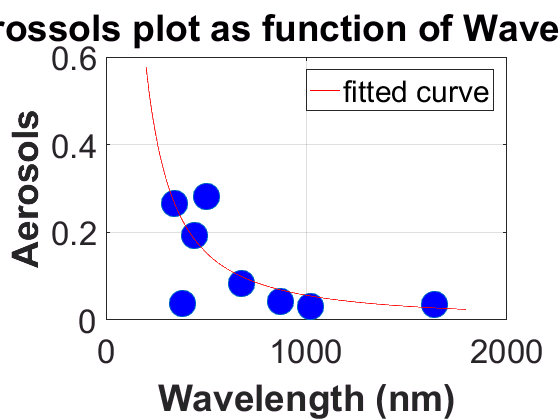

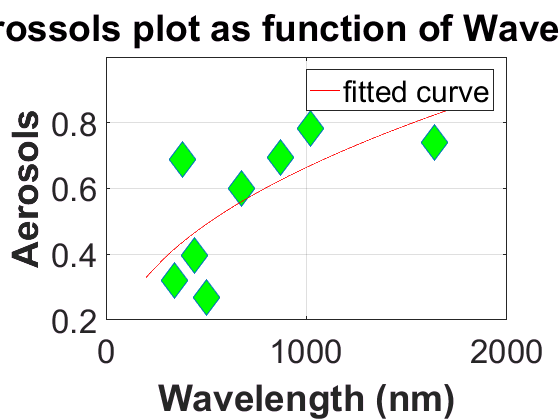

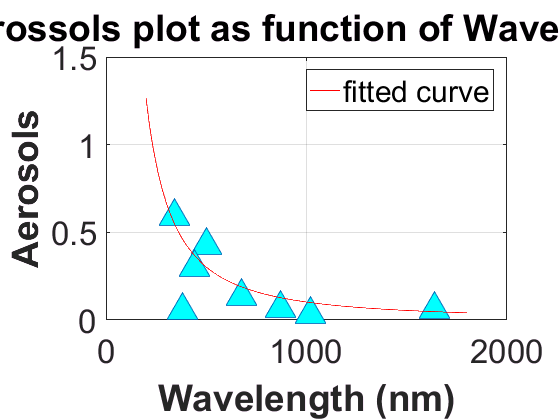

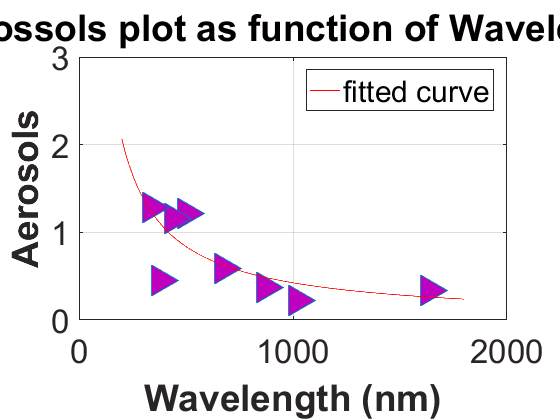

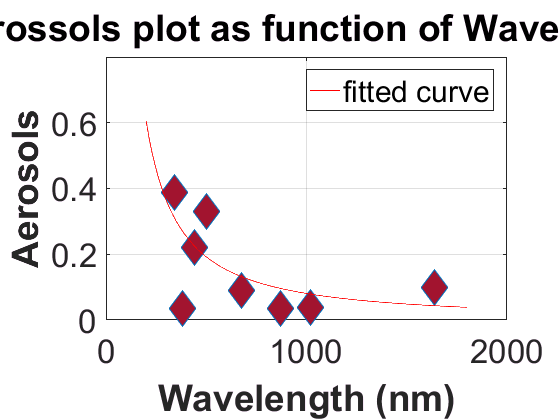

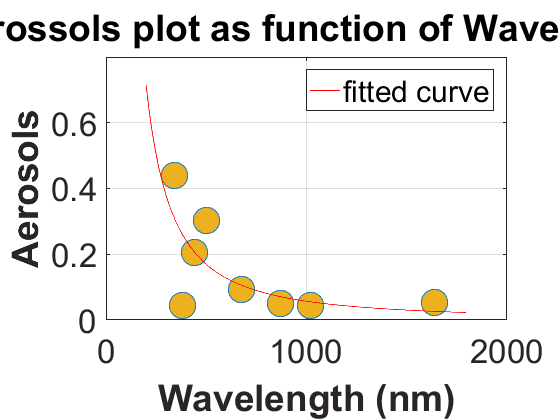

ft = fittype( 'b*x^(-a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Algorithm = 'Levenberg-Marquardt';
opts.Display = 'Off';
opts.Robust = 'Bisquare';
marker = {'<','*','o','d','^','>','d','o'};
color = {'y','r','b','g','c',[0.75, 0, 0.75],[0.6350, 0.0780, 0.1840],[0.9290, 0.6940, 0.1250]};
for i = 1:8
    [fitResult,gof] = fit(transpose(wavelength),summaryTable(i).a.Tau_aerosol,ft,opts);
    x = coeffvalues(fitResult);
    value_beta(i) = x(2);
    aer_937_nm(i) = feval(fitResult,937);
    aer_55o_nm(i) = feval(fitResult,550);
    figure
    plot(wavelength,summaryTable(i).a.Tau_aerosol,'Marker',marker{i},'LineStyle','None','MarkerFaceColor',color{i},'MarkerSize',20)
    titletext = 'Block' + num2str(i);
    hold on
    plot(fitResult)
    xlabel('Wavelength (nm)','FontWeight','bold');
    ylabel('Aerosols','FontWeight','bold');
    title('Aerossols plot as function of Wavelength');
    ax = gca;
    ax.FontSize = 25;
    grid on
end

## calculating the visibility of the data


$$\beta \text{ }=0\ldotp 613∗e^{−\frac{VIS}{15}}$$


for i = 1:8
    VIS_value(i) = log(0.613/value_beta(i))*15
end

VIS_value = -151.7018

VIS_value =  -151.7018   17.2453


VIS_value =  -151.7018   17.2453 -114.0303


VIS_value =  -151.7018   17.2453 -114.0303   43.9932


VIS_value =  -151.7018   17.2453 -114.0303   43.9932 -134.8261


VIS_value =  -151.7018   17.2453 -114.0303   43.9932 -134.8261  -96.3045


VIS_value =  -151.7018   17.2453 -114.0303   43.9932 -134.8261  -96.3045  -99.4068


VIS_value =  -151.7018   17.2453 -114.0303   43.9932 -134.8261  -96.3045  -99.4068 -127.1029


## Performing the same processing for the water content using the 940 nm data


$$ln\left(V_{\lambda } ∗D^2 \right)+\text{ }m∗\tau_{936} =ln\left(V_{936} \right)−a∗W^b ∗m^c$$


a = 0.68377;
b = 0.6126;
c = 0.6126; 

logResponse_937 = logTransformedV(:,4)

logResponse_937 =    13.5842
   13.5703
   13.5601
   13.5266
   13.4841
   13.4774
   13.4677
   13.4573
   13.4419
   12.6712


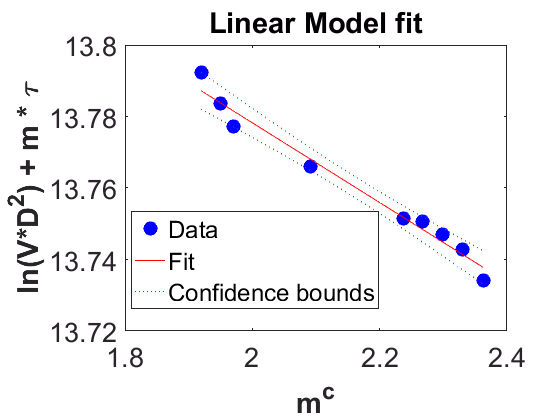

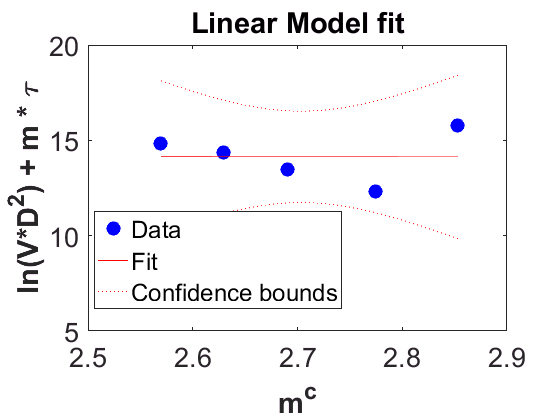

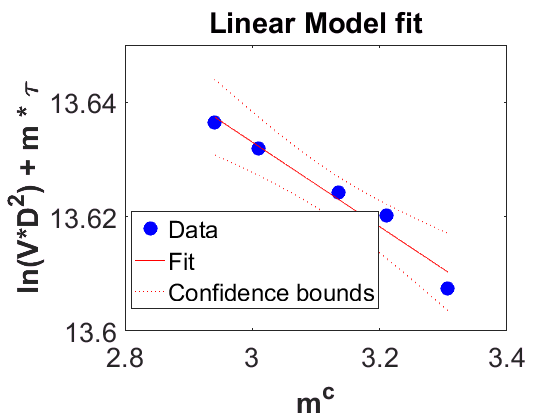

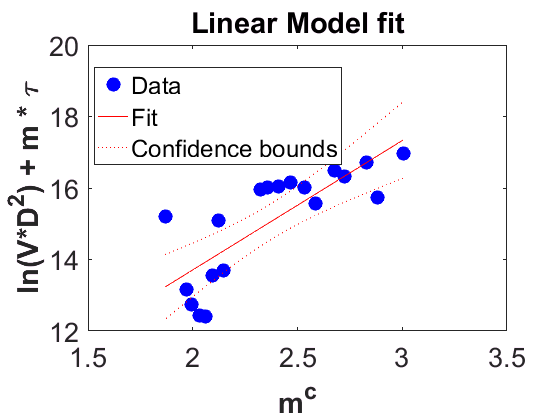

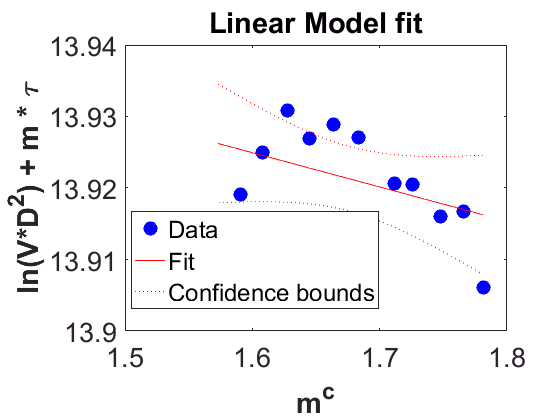

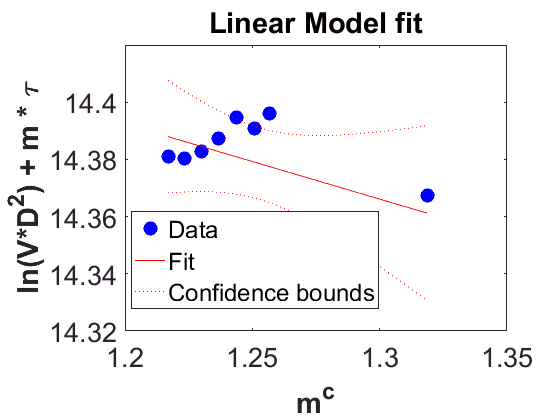

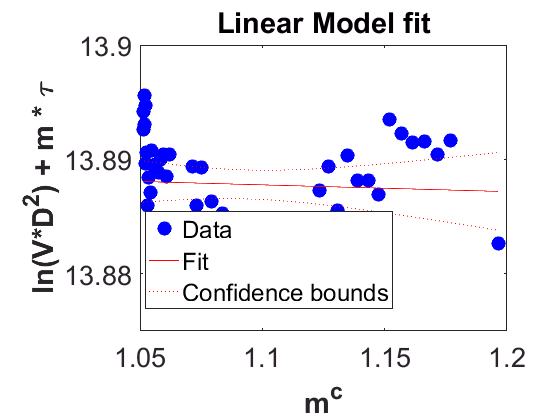

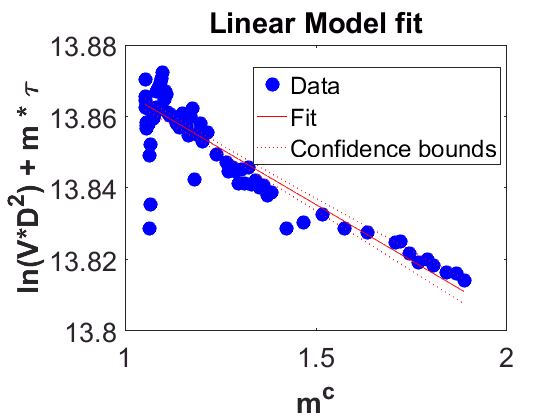

for i = 1:8
    yResponseSecond = airmass * aer_937_nm(i);
    yResponse(:,i) = logResponse_937 + yResponseSecond;
end
xPredictor = airmass.^(c);



    summaryCell2 = cell(8,6);
    % predictedReflectance = zeros(size(solarFiltered,1),7);
    % fitting regression line for the each band 
   
    x = 1:8;
    for i = x
        % Entering all the data into the table for the linear fit
        lineFitTable = table(yResponse(subset(i).a,i),xPredictor(subset(i).a));
        lineFitTable.Properties.VariableNames = {'yResponse','xPredictor'};
        model  = fitlm(lineFitTable,'yResponse ~ xPredictor','Robust','on');
        % coefficients of the linear fit 
        [coeffrow ,~] = size(model.Coefficients.Estimate);
       
        figure 
        plot(model,'Marker','o','MarkerFaceColor','b','MarkerSize',10);
        titleText = strcat('Linear Model fit');
        title(titleText)
        xlabel('m^{c}','Interpreter','tex','FontWeight','Bold');
        ylabel('ln(V*D^{2}) + m * \tau','Interpreter','tex','FontWeight','Bold');
        ax = gca;
        ax.FontSize = 20;
        
      
%         figure 
%         plot(model,'Marker','o');
%         titleText = strcat('Linear Model fit');
%         title(titleText)
%         xlabel('m^c');
%         ylabel('y');
%         ax = gca;
%         ax.FontSize = 20;
        

       
%         
%         % Displaying the model fit statistics 
%         disp(strcat('#######################################################'));
%         textValue = strcat('Model ' , num2str(i)); 
%         warning(textValue);
%         disp(model)
%         
%         %{
%         H0: The relationship assumed in the model is reasonable, i.e., there is no lack of fit.
%         HA: The relationship assumed in the model is not reasonable, i.e., there is lack of fit.
%         %}
%         
%         % analysis of variance 
%         anova(model,'summary')
%         
%         disp(strcat('#######################################################'));
%         
        summaryCell2(i,:) = {x(i); model.Rsquared.Ordinary*100; ...
            model.Rsquared.Adjusted*100; model.RMSE*100; model.Coefficients.Estimate(1); ...
            model.Coefficients.Estimate(2)}; 
        
    end

    summaryTable2 = cell2table(summaryCell2);
   clear summaryCell2
    summaryTable2.Properties.VariableNames = {'section', 'Rsquared', ...
        'AdjustedRsquared', 'RMSE','Intercept','Slope'};
    
        
        
        

## Water content

water = (abs(summaryTable2.Slope)/a).^(1/b)

water =     0.0518
    0.0086
    0.0265
   15.1740
    0.0131
    0.2102
    0.0004
    0.0203


**Function to split the cell**

 function[hh,mm,ss] = cellsplit(data,delimeter)
     for i = 1:size(data,1)
         a = strsplit(data{i},delimeter);
         hh(i) = str2double(a{1});
         mm(i) = str2double(a{2});
         ss(i) = str2double(a{3});
     end 
 end

 
 